# Laboratory1 : Pick and Place of a Spherical Manipulator

## Objective:

    to solve and to create the Pick and Place Program Mechanical Manipulator (In this case, Spherical Manipulator)

## Algorithm:

    1. Identify the Link Length

    2. Create a Denavit Hartenberg Paramteric Table

    3. Plug-in the Matrix of the following Manipulator

    4. Matrix Multiply the Transformation Matrices.

    5. Once done, we can get the Jacobian matrix by jacob0()

    6. The following Coordinates will be defined via the ikine() method

    7. Use step 2 to Plot the Trajectories

## Conventions Used:

    a_<number> - Constant Link Length

    theta = Joint Offset

    alpha = Link Twist

    r = Link Length

    d = Link Offset

### Display the Lengths

% Clear All Defined Variables

clear all;
clc;

disp("Spherical Manipulator")

Spherical Manipulator



syms a1 a2 a3

% Link Lengths a1 to a3

a1 = 20; %20m
a2 = 10; %15m
a3 = 10; %15m

### Defining the DH Parameters

In, Python, we tend to compute the Matrix of it based on the specific angles given. Since in Reality, Mechanical Manipulators tend not to work on this way. We must program a mathematical model of machanical manipulators to visualize the movement itself.

% Take note of theta, alpha, r/a, and d
H_01 = Revolute('alpha', pi/2, 'd', a1)

 
H_01 = 
Revolute(std): theta=q, d=20, a=0, alpha=1.5708, offset=0


H_12 = Revolute('alpha', pi/2, 'offset', pi/2)

 
H_12 = 
Revolute(std): theta=q, d=0, a=0, alpha=1.5708, offset=1.5708


H_23 = Prismatic('offset', a2 + a3)

 
H_23 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=20



%Defining the Joint Limits (IRL it has following limits of course)

H_01.qlim = pi/180 * [-90, 90];
H_12.qlim = pi/180 * [-90, 90];
H_23.qlim = [0, 50];

### Combining the DH Parameters into a `SerialLink` object

Once created the following DH Parameters, we can connect using a SerialLink object. This displays the DH Parametric Table we've discussed in Robotics 1

Spherical = SerialLink([H_01, H_12,H_23], 'name', 'Spherical Manipulator')

 
Spherical = 
 
Spherical Manipulator:: 3 axis, RRP, stdDH, slowRNE              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         20|          0|     1.5708|          0|
|  2|         q2|          0|          0|     1.5708|     1.5708|
|  3|          0|         q3|          0|          0|         20|
+---+-----------+-----------+-----------+-----------+-----------+
 


### Plotting and Teaching the Robot

Once done, we are about to plot the robot in the origin, and teach the robot (Have Sliders to know the position of the end effector based on the jont angles)

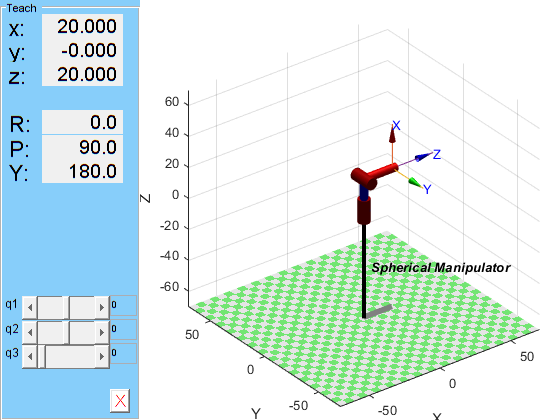

origin = [0 0 0];
workspace = [-25,25,-25,25,-10,25];
Spherical.plot(origin);
Spherical.teach();

#### Jacobian Matrix Generation

For the Generation of Jacobian Matrix, we can able to generate using jacob0() command

J_TestValue1 = jacob0(Spherical, [-pi/2,-pi/2,0])

J_TestValue1 =     0.0000    0.0000   -0.0000
   -0.0000  -20.0000   -0.0000
    0.0000         0   -1.0000
         0   -1.0000         0
         0   -0.0000         0
    1.0000    0.0000         0


J_TestValue2 = jacob0(Spherical, [-pi/4,-pi/4,12.5])

J_TestValue2 =    16.2500   16.2500    0.5000
   16.2500  -16.2500   -0.5000
    0.0000   22.9810   -0.7071
    0.0000   -0.7071         0
    0.0000   -0.7071         0
    1.0000    0.0000         0


J_TestValue3 = jacob0(Spherical, [0,0,25])

J_TestValue3 =     0.0000    0.0000    1.0000
   45.0000    0.0000   -0.0000
         0   45.0000   -0.0000
   -0.0000         0         0
         0   -1.0000         0
    1.0000    0.0000         0


J_TestValue4 = jacob0(Spherical, [pi/4,pi/4,37.5])

J_TestValue4 =   -28.7500  -28.7500    0.5000
   28.7500  -28.7500    0.5000
    0.0000   40.6586    0.7071
   -0.0000    0.7071         0
   -0.0000   -0.7071         0
    1.0000    0.0000         0


J_TestValue5 = jacob0(Spherical, [pi/2,pi/2,50])

J_TestValue5 =    -0.0000   -0.0000    0.0000
    0.0000  -70.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000    1.0000         0
         0   -0.0000         0
    1.0000    0.0000         0


#### **Defining the following Coordinates of the Box and Conveyor Belt**

We Define now the coordinates of the conveyor belt and box via the ikine() command

original_pose = Spherical.ikine(SE3(30, 0, 20),'mask', [1, 1, 1, 0, 0, 0])

original_pose =     0.0000    0.0000   10.0000


conveyor_belt = Spherical.ikine(SE3(33, 0, 10),'mask', [1, 1, 1, 0, 0, 0])

conveyor_belt =     0.0000   -0.2942   14.4819


box = Spherical.ikine(SE3(33, 0, 10), 'mask', [1, 1, 1, 0, 0, 0])

box =     0.0000   -0.2942   14.4819


#### Next, we define the Trajectories of the following Pick and Place Robot

traj1 = jtraj(original_pose, conveyor_belt, 20)

traj1 =     0.0000    0.0000   10.0000
    0.0000   -0.0004   10.0060
    0.0000   -0.0029   10.0444
    0.0000   -0.0090   10.1373
    0.0000   -0.0195   10.2973
    0.0000   -0.0347   10.5283
    0.0000   -0.0543   10.8273
    0.0000   -0.0778   11.1852
    0.0000   -0.1043   11.5884
    0.0000   -0.1326   12.0202


traj2 = jtraj(conveyor_belt, original_pose, 20)

traj2 =     0.0000   -0.2942   14.4819
    0.0000   -0.2938   14.4759
    0.0000   -0.2913   14.4375
    0.0000   -0.2852   14.3446
    0.0000   -0.2747   14.1846
    0.0000   -0.2596   13.9536
    0.0000   -0.2399   13.6546
    0.0000   -0.2164   13.2967
    0.0000   -0.1900   12.8934
    0.0000   -0.1616   12.4617


traj3= jtraj(original_pose, box, 20)

traj3 =     0.0000    0.0000   10.0000
    0.0000   -0.0004   10.0060
    0.0000   -0.0029   10.0444
    0.0000   -0.0090   10.1373
    0.0000   -0.0195   10.2973
    0.0000   -0.0347   10.5283
    0.0000   -0.0543   10.8273
    0.0000   -0.0778   11.1852
    0.0000   -0.1043   11.5884
    0.0000   -0.1326   12.0202


traj4 = jtraj(box, original_pose, 20)

traj4 =     0.0000   -0.2942   14.4819
    0.0000   -0.2938   14.4759
    0.0000   -0.2913   14.4375
    0.0000   -0.2852   14.3446
    0.0000   -0.2747   14.1846
    0.0000   -0.2596   13.9536
    0.0000   -0.2399   13.6546
    0.0000   -0.2164   13.2967
    0.0000   -0.1900   12.8934
    0.0000   -0.1616   12.4617
